Consider a target shape and load that is unreachable with a regular muscle design:

N_segs = 5;
Q = [0; -3; 0];

overall_g_circ_right_goal = [0.5; 0; 1];
seg_g_circ_right_goal = overall_g_circ_right_goal / N_segs;
arm_g_circ_right_goal = repmat(overall_g_circ_right_goal, [1, N_segs]);

l_0 = overall_g_circ_right_goal(1);
rho_constant = 0.05;
test_straight_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_segs, rho_constant, l_0);
rxn_needed = test_straight_arm.calc_external_reaction(Q, arm_g_circ_right_goal);
internal_needed = -rxn_needed;

We will first show that this target point and load is not reachable with the muscles that we have designed

% Define load scenario
p = [60; 0; 60; 0];
Q = [0; -10; 0];
Q_frame = "World";
N_segments = 4;
l_0 = 0.5;

%% Create a no-taper arm
rho_outer_base = 0.06;
rho_inner_base = 0.01;
constant_arm = ArmSeriesFactory.constant_2d_antagonist_arm(N_segments, rho_inner_base, rho_outer_base, l_0);
constant_arm.set_mechanics(BasicPolyBellowMechanics(l_0), [1, 4]);
constant_arm.set_mechanics(AnnealedGinaMuscleMechanics(l_0), [2, 3]);
constant_arm.solve_equilibrium_gina(p, Q);

fzero residual is nonzero (> 0.01). Printing: 
   -0.0014   -0.0050   -0.0121   -0.0229
    0.0000    0.0001    0.0001   -0.0004
    0.1370    0.4512    1.0871    1.7862


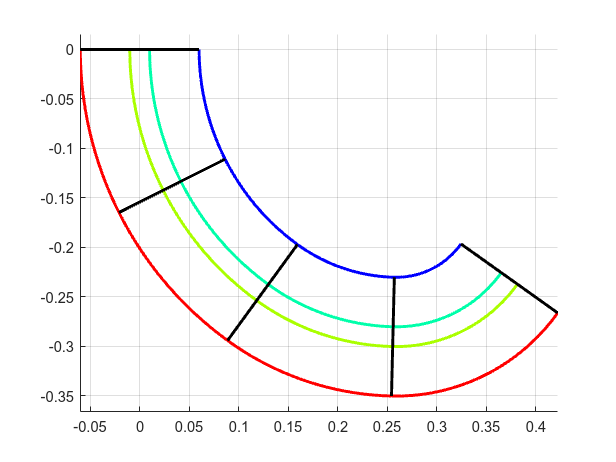

Plotter2D.plot_arm_series(constant_arm, axes(figure()));

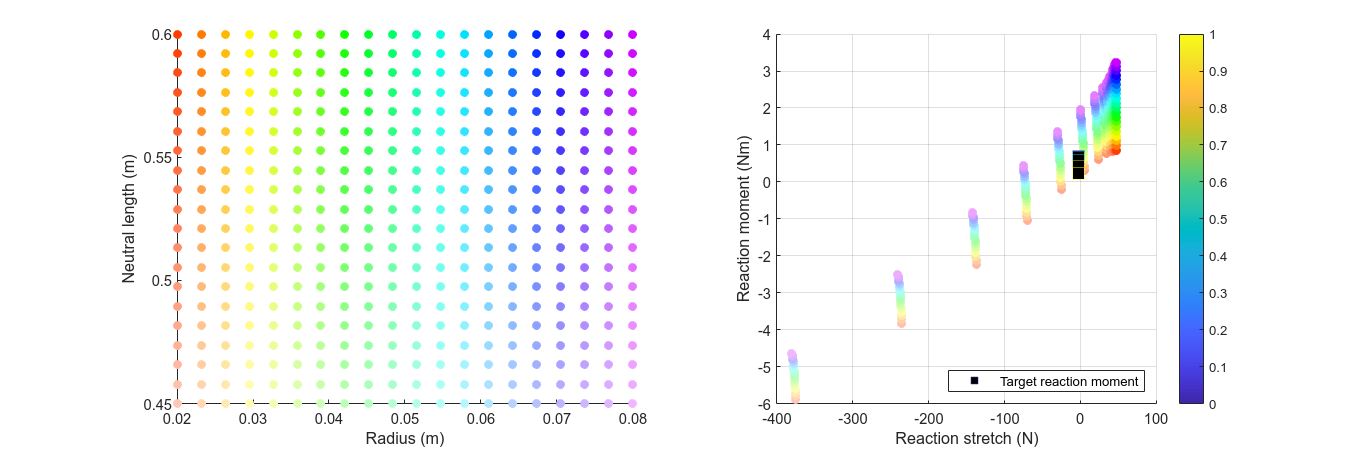

% Analyze the force function that results from combining the force
% functions of each side's muscle pair
rho_inner = 0.02;
N_rhos = 20;
N_ls = 20;
rho_outers = linspace(0.02, 0.08, N_rhos);
l_0s = linspace(0.45, 0.60, N_ls);

p_antagonist = [30; 0; 30; 0];

cell_rl = cell(N_rhos, N_ls);
cell_arm_segments = cell(N_rhos, N_ls);
cell_rxns = cell(N_rhos, N_ls);
cell_colors = cell(N_rhos, N_ls);
for i = 1 : N_rhos
    rho_i = rho_outers(i);
    for j = 1 : N_ls
        l_0_j = l_0s(j);
        % Calculate the internal reaction moment that the muscles would create
        % at that curvature.
        segment_ij = ArmSegmentFactory.make_2d_antagonism(rho_inner, rho_i, l_0_j);
        segment_ij.set_mechanics(GinaMuscleMechanics(l_0_j), [2, 3]);
        segment_ij.set_mechanics(BasicBellowMechanics(l_0_j), [1, 4]);
    
        cell_arm_segments{i, j} = segment_ij;
        cell_rl{i, j} = [rho_i; l_0_j];
        rxns_i = segment_ij.calc_internal_reaction(p_antagonist, overall_g_circ_right_goal);
        cell_rxns{i, j} = rxns_i;
        cell_colors{i, j} = [i/N_rhos * 0.8; j/N_ls * 0.75 + 0.25; 1];
    end
end

mat_rl = [cell_rl{:}];
mat_rxns = [cell_rxns{:}];
mat_hsv = [cell_colors{:}];
mat_rgb = hsv2rgb(mat_hsv');

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
scatter(mat_rl(1, :), mat_rl(2, :), [], mat_rgb, "filled");
xlabel("Radius (m)");
ylabel("Neutral length (m)")

subplot(1, 2, 2);
hold on
scatter(mat_rxns(1, :), mat_rxns(3, :), [], mat_rgb, "filled");
scatter(internal_needed(1, :), internal_needed(3, :), 100, linspace(0, 1, N_segs), 'square', "markerfacecolor", 'k')
colorbar

grid on
xlabel("Reaction stretch (N)")
ylabel("Reaction moment (Nm)")
legend(["", "Target reaction moment"], "location", "southeast")